# Fehlerschätzung bei Fixpunktiterationen

Wir betrachten folgende zwei Fixpunktiterationen:

         $x_{k+1} =\Phi_1(x_k), ~~ \Phi_1(x)=\frac12 (x+\frac{2}{x})
$,

         
$$x_{k+1} =\Phi_2(x_k), ~~ \Phi_2(x)=\frac{1}{x^2}+x-\frac12.
$$


Es gilt: $\Phi_i(\sqrt{2})=\sqrt{2},\quad i=1,2$, und $\Phi_1'(\sqrt{2})=0,~~0< \Phi_2'(\sqrt{2}) <1.$

Für die Fixpunktiteration mit $\Phi_1$ verwenden wir die Fehlerschätzung:

          
$$\sqrt{2}-x_k \approx x_{k+1}-x_k=:{\rm err1}_{\rm est},\quad k \geq 0,$$


und für $\Phi_2$:

        
$$\sqrt{2}-x_k \approx \frac{A_k}{1-A_k}(x_{k}-x_{k-1})=:{\rm err2}_{\rm est},~~~A_k:=\frac{x_k-x_{k-1}}{x_{k-1}-x_{k-2}}, \quad k\geq 2.$$


Wir wählen einen Startwert $x_0 \in [\frac12,3]$

fprintf('\n Startwert: \n');


 Startwert: 


x0=0.5

x0 = 0.5000

Mit beiden Fixpunktiterationen werden 10 Iterationen mit diesem Startwert berechnet.

Die entsprechenden Fehlerschätzungen und exakten (bis auf Maschinengenauigkeit) Fehler werden bestimmt.

# Aktivität:

Variieren Sie den Startwert $x_0$ und untersuchen Sie die Qualität der Fehlerschätzer.

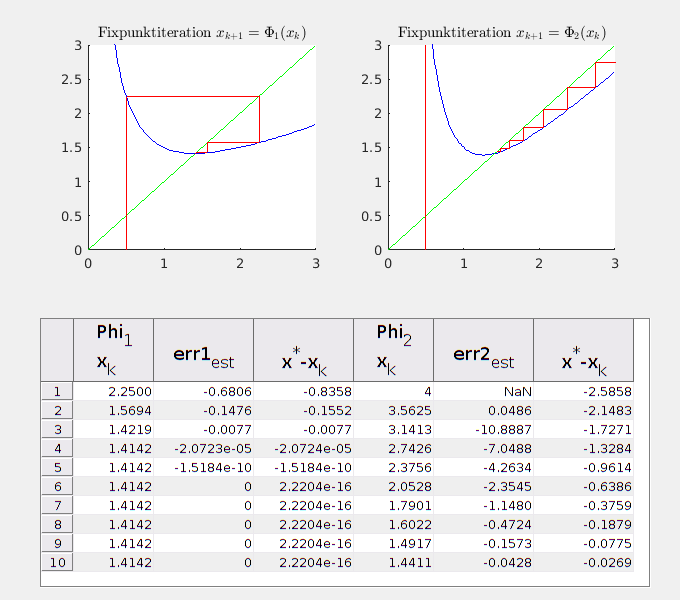

Erg=zeros(11,7);
%% Initialisierung
loop=11;
xn=x0;
xf=x0;
xnm2=xn;
xfm2=xf;

Erg(1,2)=xn;
Erg(1,5)=xf;

%% erste Iteration
xn=newton(xn);
xf=fixpunkt(xf);
xnm1=xn;
xfm1=xf;

Erg(2,2)=xn;
Erg(2,3)=newton(xn)-xn;
Erg(2,4)=sqrt(2)-xn;
Erg(2,5)=xf;
Erg(2,6)=NaN;
Erg(2,7)=sqrt(2)-xf;

%% Iterationen 2 bis 10
for i=3:loop

    xn=newton(xn);
    xf=fixpunkt(xf);
    % Einträge für Phi_1
    Erg(i,1)=i;
    Erg(i,2)=xn;
    Ank=(xn-xnm1)/(xnm1-xnm2);
    Erg(i,3)=newton(xn)-xn;
    xnm2=xnm1;
    xnm1=xn;
    Erg(i,4)=sqrt(2)-xn;
    % Einträge für Phi_2
    Erg(i,5)=xf;
    Afk=(xf-xfm1)/(xfm1-xfm2);
    Erg(i,6)=Afk/(1-Afk)*(xf-xfm1);
    xfm2=xfm1;
    xfm1=xf;
    Erg(i,7)=sqrt(2)-xf;
end

%% Plot der Fixpunktiterationen
visualize(Erg);

function xip1=fixpunkt(xi)
xip1= 1./(xi.*xi) + xi - 0.5;

end

function xip1=newton(xi)
xip1= 0.5 * ( xi + 2./xi );
end

function hp1=htmlp1(s)
hp1=strcat('<html><FONT size="+1">',   s    ,'</font></html>');
end

function visualize(Erg)
clf reset;
f=figure('Position',[1 1 680 600],'NumberTitle',"off",...
    'Name',"Fixpunktiteration und Fehlerschätzer");
movegui(f,'northeast');
loop=size(Erg,1);
subplot(2,2,1);
hold on;
axis([ 0 3 0 3]);
fplot(@(x) newton(x),[0 3],'b')
plot([0 3],[0 3],'g');
plot([Erg(1,2) Erg(1,2)],[0 newton(Erg(1,2))],'r');
title('Fixpunktiteration $x_{k+1}=\Phi_1(x_k)$','Interpreter','latex');
for i=1:loop-1
    plot([Erg(i+1,2) Erg(i+1,2)], [Erg(i+1,2) newton(Erg(i+1,2))],'r')
    plot([Erg(i+1,2) Erg(i,2)], [newton(Erg(i,2))  Erg(i+1,2)],'r');
end
hold off;
subplot(2,2,2);
hold on;
axis([ 0 3 0 3]);
fplot(@(x) fixpunkt(x),[0 3],'b')
plot([0 3],[0 3],'g');
plot([Erg(1,5) Erg(1,5)],[0 fixpunkt(Erg(1,5))],'r');
title('Fixpunktiteration $x_{k+1}=\Phi_2(x_k)$','Interpreter','latex');
for i=1:loop-1
    plot([Erg(i+1,5) Erg(i+1,5)], [Erg(i+1,5) fixpunkt(Erg(i+1,5))],'r')
    plot([Erg(i,5) Erg(i+1,5)], [fixpunkt(Erg(i,5))  Erg(i+1,5)],'r');
end

%% Tabelle mit Ergebnissen
uitable(f,'Data',Erg(2:loop,2:7),...
    'FontSize',10,...
    'ColumnWidth',{80 100 100 80 100 100},...
    'ColumnName',{htmlp1('Phi<sub>1</sub><br>x<sub>k</sub>'),...
    htmlp1(' <br>err1<sub>est</sub>'),...
    htmlp1(' <br>x<sup>*</sup>-x<sub>k</sub>'),...
    htmlp1('Phi<sub>2</sub><br>x<sub>k</sub>'),...
    htmlp1(' <br>err2<sub>est</sub>'),...
    htmlp1(' <br>x<sup>*</sup>-x<sub>k</sub>')},...
    'Units','normalized','Position',[  .06 .02 .9 .45]);

end